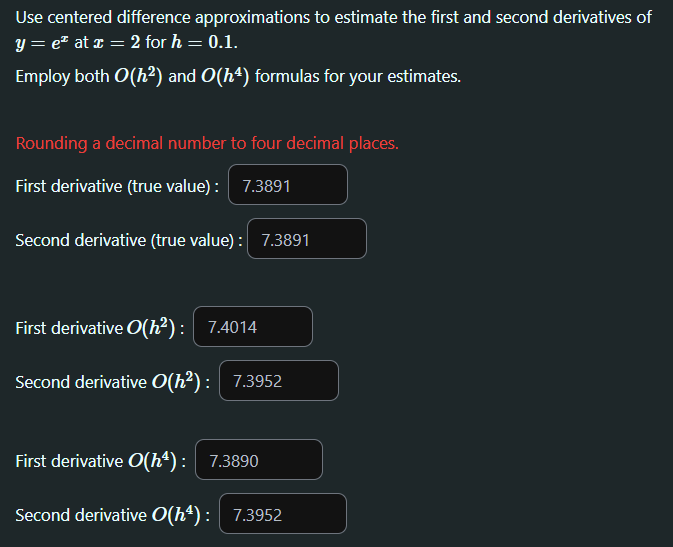

f = @(x) exp(x);
xi = 2;
h = 0.1;

xi_2 = xi - 2*h;
xi_1 = xi - h;
xi;
xi1 = xi + h;
xi2 = xi + 2*h;

compute

df = @(x) exp(x);

diff_xi_true1st = df(xi)

diff_xi_true1st = 7.3891

diff_xi_true2nd = df(xi)

diff_xi_true2nd = 7.3891

Centered diff O(h^2)

centered_1st_h = ( f(xi1) - f(xi_1) ) / (2*h)

centered_1st_h = 7.4014

et = Et(diff_xi_true1st,centered_1st_h);
centered_2nd_h = ( f(xi1) - 2*f(xi) + f(xi_1) ) / (h^2)

centered_2nd_h = 7.3952

et = Et(diff_xi_true1st,centered_2nd_h);

Centered diff O(h^4)

centered_1st_h4 = ( -f(xi2) + 8*f(xi1) - 8*f(xi_1) + f(xi_2) ) / (12*h)

centered_1st_h4 = 7.3890

centered_2nd_h4 = ( f(xi1) - 2*f(xi) + f(xi_1) ) / (h^2)

centered_2nd_h4 = 7.3952